Given a causal stable IIR low-pass filter


$$H(z) =\frac{\frac{1-\alpha}{2}(1+z^{-1})}{1-\alpha z^{-1}}$$


with $\alpha = 0.5$. 

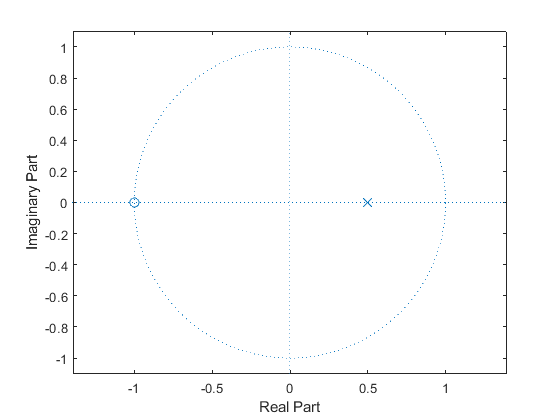

w = pi*[0:0.001:1];  % normalized frequencies
alpha = 0.5;
blp = (1-alpha)/2*[1 1];    % numerator coefficients
alp = [1 -alpha];           % denominator coefficients
hlp = freqz(blp,alp,w);     % frequency response
glp = grpdelay(blp,alp,w);  % group delay
zplane(blp,alp)

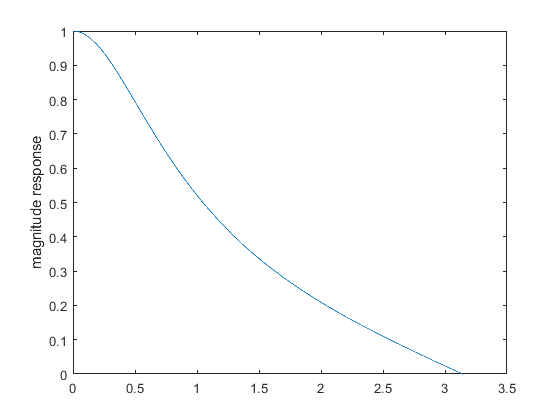

plot(w,abs(hlp)), ylabel('magnitude response')

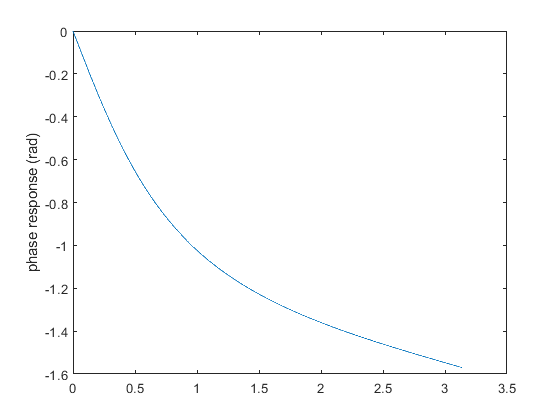

plot(w,angle(hlp)), ylabel('phase response (rad)')

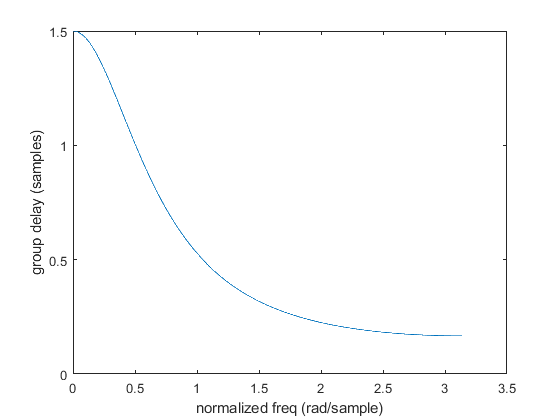

plot(w,glp), ylabel('group delay (samples)'),xlabel('normalized freq (rad/sample)')

We will cascade a causal all-pass filter with the LPF to linearize the phase response and equalize the group delay in the passband.

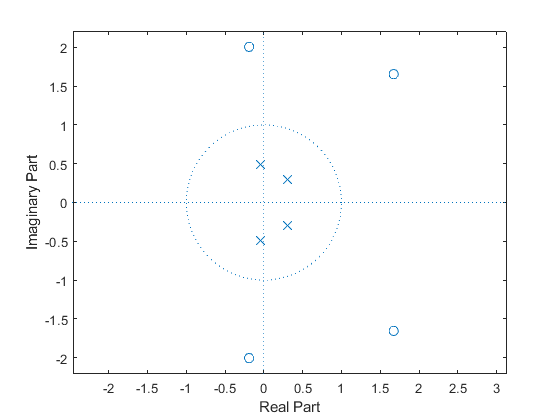

N = 4;                          % all-pass filter order
freqs = (1:ceil(length(w)/2));  % indices of half of the frequencies
F = w(freqs)/pi;                % normalized frequencies
edges = [0 1/2];                % band-edge frequencies
Gd = max(glp)-glp(freqs);        % desired group delays of apf 
[bap,aap] = iirgrpdelay(N,F,edges,Gd); % all - pass filter
hap = freqz(bap,aap,w);         % compute DTFT
gap = grpdelay(bap,aap,w);      % compute groupdelay
zplane(bap,aap)

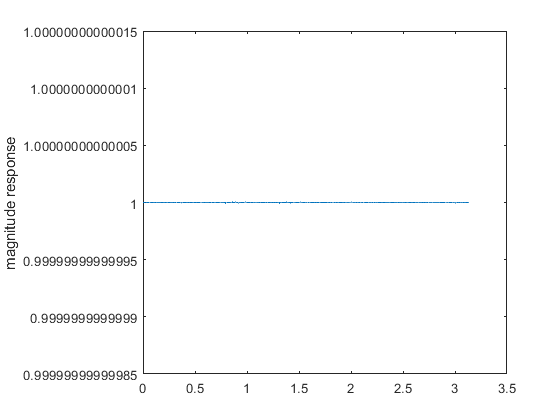

plot(w,abs(hap)), ylabel('magnitude response')

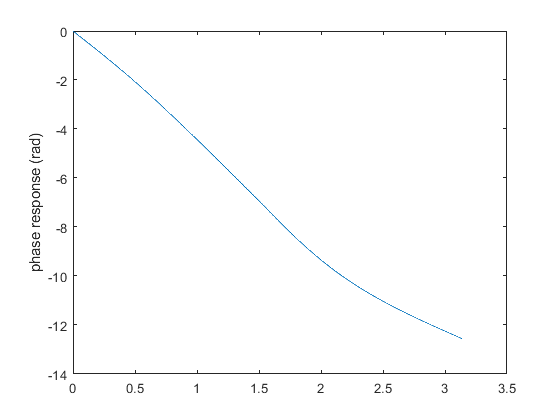

plot(w,unwrap(angle(hap))), ylabel('phase response (rad)')

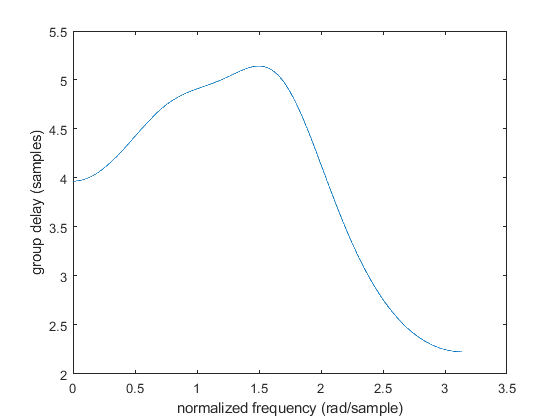

plot(w,gap), ylabel('group delay (samples)'), xlabel('normalized frequency (rad/sample)')

Compute and plot the cascaded response

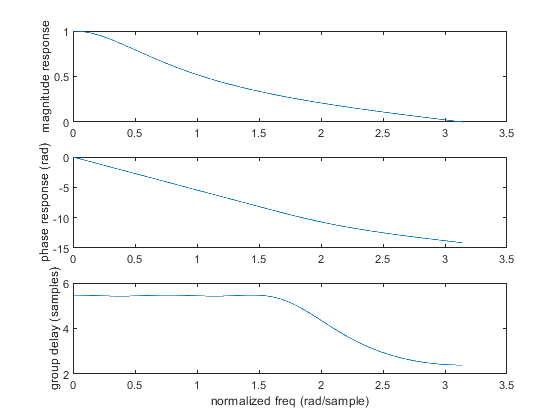

b = conv(blp,bap);          % product of the numerators
a = conv(alp,aap);          % product of the denominators
h = freqz(b,a,w);           % DTFT
g = grpdelay(b,a,w);        % group delay
subplot(3,1,1)
plot(w,abs(h)), ylabel('magnitude response')
subplot(3,1,2)
plot(w,unwrap(angle(h))), ylabel('phase response (rad)')
subplot(3,1,3)
plot(w,g), xlabel('normalized freq (rad/sample)'), ylabel('group delay (samples)')